# **Iniciação Científica**

#### Tema: Análise de Eficiência de Desacopladores e Técnicas de Projeto de Controladores PI SISO para Processos de Moagem

**Voluntária IC:** Grazielle Amanda do Carmo Café

**Orientador:** Dr. Márcio Braga

close all
clearvars

## **Modelo descrito por Ivezic e Petrovic (2003)**

### Etapa 1 - Desacopladores

% Descrição do Modelo: 
s = tf('s', 'TimeUnit', 'seconds');
G(1,1) = (-0.9362)/(1164*s + 1);
Ga(1,1) = exp(-350*s);
Gd(1,1) = -350;

G(1,2) = (10.252*s + 2.819*10^(-3))/(80218*s^2 + 652*s +1);
Ga(1,2) = exp(-200*s);
Gd(1,2) = -200; 

G(2,1) = (36.49)/(792*s+1);
Ga(2,1) = 1;
Gd(2,1) = 0; 

G(2,2) = (1.1405)/(179*s+1);
Ga(2,2) = 1;
Gd(2,2) = 0

Gd =   -350  -200
     0     0




% Função de Transferência G: 
G                        % Sem atraso

G =
 
  From input 1 to output...
        -0.9362
   1:  ----------
       1164 s + 1
 
         36.49
   2:  ---------
       792 s + 1
 
  From input 2 to output...
        10.25 s + 0.002819
   1:  ---------------------
       80218 s^2 + 652 s + 1
 
         1.141
   2:  ---------
       179 s + 1
 
Continuous-time transfer function.



Gdelay = Ga              % Atrasos presentes no sistema

Gdelay =
 
  From input 1 to output...
   1:  exp(-350*s) * (1)
 
   2:  1
 
  From input 2 to output...
   1:  exp(-200*s) * (1)
 
   2:  1
 
Continuous-time transfer function.



Gmodel = G.*Gdelay       % Função de transferência G do modelo        

Gmodel =
 
  From input 1 to output...
                      -0.9362
   1:  exp(-350*s) * ----------
                     1164 s + 1
 
         36.49
   2:  ---------
       792 s + 1
 
  From input 2 to output...
                      10.25 s + 0.002819
   1:  exp(-200*s) * ---------------------
                     80218 s^2 + 652 s + 1
 
         1.141
   2:  ---------
       179 s + 1
 
Continuous-time transfer function.



**Desacoplador Estático**

Gstatic = evalfr(Gmodel,0);
Dstatic = inv(Gstatic);
out = Gmodel*Dstatic

out =
 
  A = 
               x1          x2          x3          x4          x5
   x1  -0.0008591           0           0           0           0
   x2           0   -0.001263           0           0           0
   x3           0           0   -0.008128   -0.003191           0
   x4           0           0    0.003906           0           0
   x5           0           0           0           0   -0.005587
 
  B = 
              u1         u2
   x1   -0.03045  7.526e-05
   x2    -0.2436   0.000602
   x3     0.4871     0.0125
   x4          0          0
   x5      1.948    0.04998
 
  C = 
              x1         x2         x3         x4         x5
   y1   -0.02574          0   0.008179  0.0005758          0
   y2          0     0.1843          0          0     0.1019
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
 
  (values computed with all internal delays set to zero)

  Output delays (seconds): 200  0 
  Internal delays (seconds): 150 
 
Continuous-time state-space model.



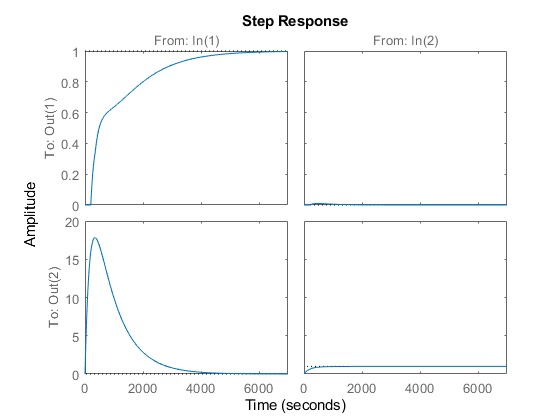

step(out)


% Análise dos Índices de Desempenho
[pv, t] = step(out)

pv = pv(:,:,1) =
         0         0
         0    2.3958
         0    4.5314
         0    6.4307
         0    8.1156
         0    9.6059
         0   10.9196
         0   12.0733
         0   13.0818
         0   13.9590
         0   14.7172
         0   15.3678
         0   15.9211
    0.0540   16.3864
    0.1088   16.7723
    0.1568   17.0866
    0.1985   17.3364
    0.2346   17.5281
    0.2658   17.6675
    0.2924   17.7601
    0.3151   17.8105
    0.3342   17.8233
    0.3600   17.8024
    0.3858   17.7515
    0.4089   17.6738
    0.4296   17.5724
    0.4481   17.4500
    0.4648   17.3090
    0.4797   17.1517
    0.4930   16.9801
    0.5050   16.7960
    0.5158   16.6012
    0.5255   16.3970
    0.5343   16.1849
    0.5422   15.9662
    0.5494   15.7418
    0.5559   15.5129
    0.5618   15.2803
    0.5673   15.0449
    0.5722   14.8073
    0.5768   14.5682
    0.5811   14.3283
    0.5850   14.0880
    0.5887   13.8478
    0.5922   13.6082
    0.5955   13.3695
    0.5986   13.1

t = 	1.0e+03 *

         0
    0.0165
    0.0330
    0.0495
    0.0659
    0.0824
    0.0989
    0.1154
    0.1319
    0.1484



sp = zeros(size(t,1),1);
% sp = 0;
erro = sp - pv;
indice.IAE = trapz(abs(erro));
indice.ITAE = trapz(t.*abs(erro));
indice.ISE = trapz(erro.^2);


### Etapa 2 - Projeto de Controladores

Técnica de Sintonia IMC

% Controle C1 a partir de G(1,1): 

k_1 = 1; 
theta_1 = 350;
tau_1 = 1164;
tauc_1 = theta_1;

% Parâmetros
kck_1 = (tau_1 + theta_1) / (k_1*(tauc_1 + theta_1));
ti_1 = tau_1;
ki_1 = kck_1 / ti_1; 
td_1 = 0;
kd_1 = kck_1 * td_1;

% Controle 
C1 = pid(kck_1, ki_1, kd_1)

C1 =
 
             1 
  Kp + Ki * ---
             s 

  with Kp = 2.16, Ki = 0.00186
 
Continuous-time PI controller in parallel form.




% Controle C2 a partir de G(2,2): 
k_2 = 1; 
tau_2 = 179;
tauc_2 = tau_2 * 0.1;

% Parâmetros
kck_2 = (tau_2) / (k_2*(tauc_2));
ti_2 = tau_2;
ki_2 = kck_2 / ti_2; 
td_2 = 0;
kd_2 = kck_2 * td_2;

% Controle 
C2 = pid(kck_2, ki_2, kd_2)

C2 =
 
             1 
  Kp + Ki * ---
             s 

  with Kp = 10, Ki = 0.0559
 
Continuous-time PI controller in parallel form.




% Simulação
spaceG11 = ss(Gmodel(1,1));
spaceG12 = ss(Gmodel(1,2));
spaceG21 = ss(Gmodel(2,1));
spaceG22 = ss(Gmodel(2,2));

% Did = eye(2,2);

sim('Simulink_Ivezic_2x2.slx')

No system or file called 'Simulink_Ivezic_2x2.slx' found.